**Paer2-1:** Load data and Extract input and output variables from the data 

    Attribute Information:

-   column 1. mpg:           continuous

-   column 2. cylinders:     multi-valued discrete

-   column 3. displacement:  continuous

-   column 4. horsepower:    continuous

-   column 5. weight:        continuous

-   column 6. acceleration:  continuous

-   column 7. model year:    multi-valued discrete

-   column 8. origin:        multi-valued discrete

clear all;
close all;

%% Add code:
% complete the lines of code for data loading 
data = load('car_mpg.csv');


%Add code: extract cylinders, displacement, and horse power as input
Cylinders = data(:,2);
Displacement = data(:,3);
HorsePower = data(:,4);


%Add code: extract mpg as target output
TargetOutputMPG = data(:,1);


**Part2-2**: Plot the data for the visualization :  

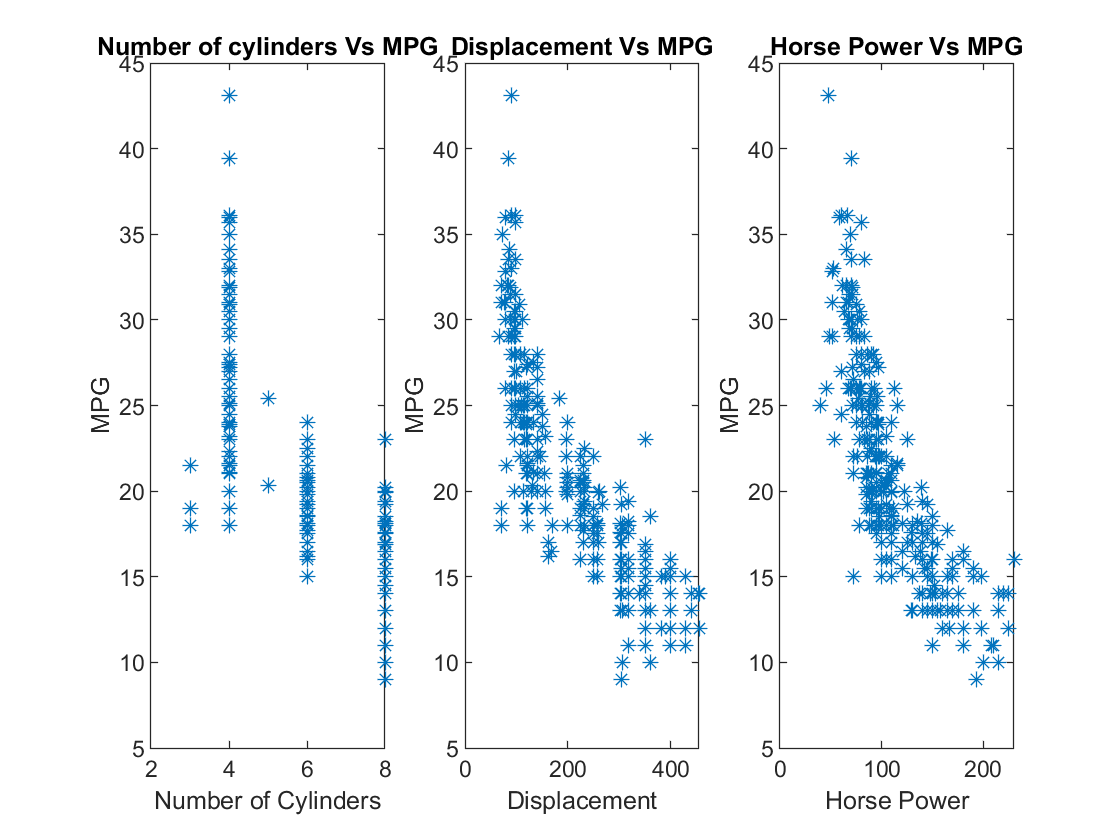

%add lines of code for data visualization
figure(1)

subplot(1,3,1)
%add code:plot the first input feature vs. mpg

plot(Cylinders,TargetOutputMPG,'*');xlabel('Number of Cylinders'); ylabel('MPG');

title('Number of cylinders Vs MPG');


subplot(1,3,2)
%add code:plot the second input feature vs. mpg

plot(Displacement,TargetOutputMPG,'*');xlabel('Displacement'); ylabel('MPG');
title('Displacement Vs MPG');



subplot(1,3,3)
%add code:plot the third input feature vs. mpg

plot(HorsePower,TargetOutputMPG,'*');xlabel('Horse Power'); ylabel('MPG');
title('Horse Power Vs MPG');

**Part2-3**: Data Normalization : In machine learning, data normalization is a procedure that m**akes input features are in the similar ranges. **And another reason why data normalization is applied that  **Gradient descent converges much faster with feature scaling than without feature scaling. **

% add lines of code for data normalization 
% Use the standardization method which uses the mean and the standard deviation of the feature. 
meanCylinders = mean(Cylinders);
meanDisplacement = mean(Displacement);
meanHorsePower = mean(HorsePower);

sigmaCylinders = std(Cylinders);
sigmaDisplacement = std(Displacement);
sigmaHorsePower = std(HorsePower);

normalizedCylinders = (Cylinders - meanCylinders) ./ sigmaCylinders;
normalizedDisplacement = (Displacement - meanDisplacement) ./ sigmaDisplacement;
normalizedHorsePower = (HorsePower - meanHorsePower) ./ sigmaHorsePower;





**Part2-4:** Plot the normalized data for the visualization : 

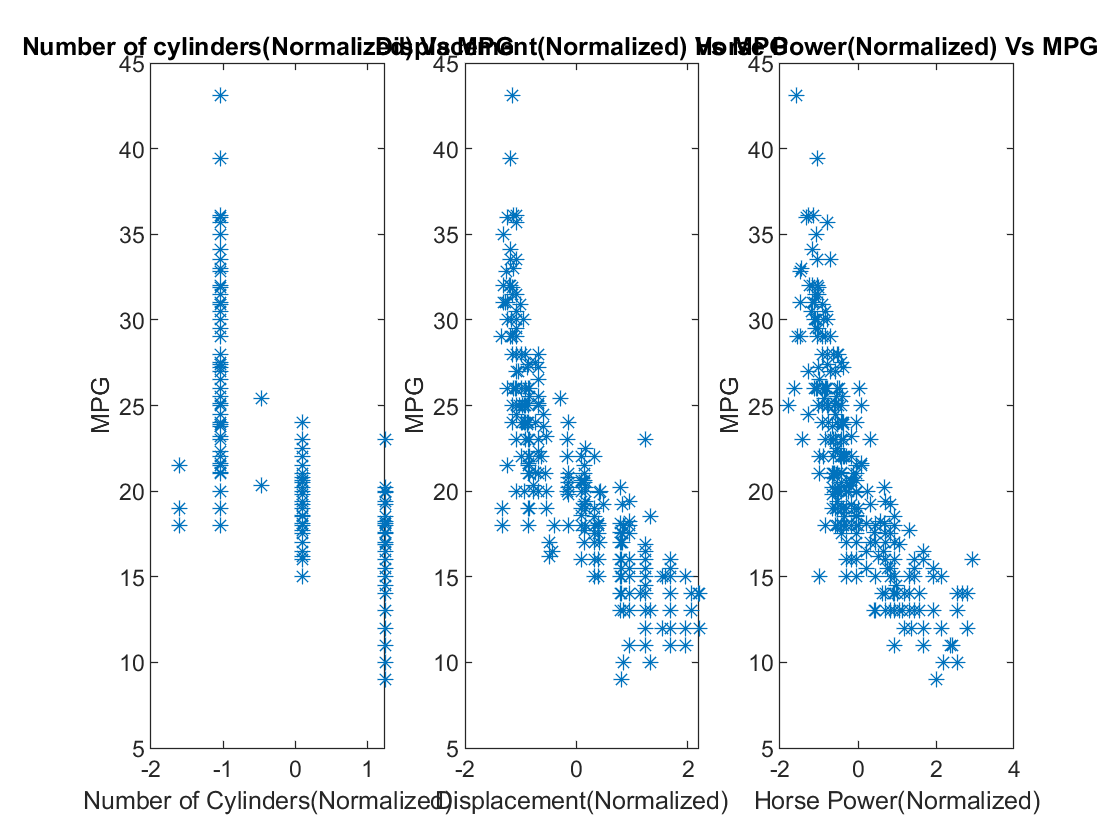

figure(2)

%add lines of code for data visualization
figure(1)

subplot(1,3,1)
%add code:plot the first normalized input feature vs. mpg

plot(normalizedCylinders,TargetOutputMPG,'*');xlabel('Number of Cylinders(Normalized)'); ylabel('MPG')
title('Number of cylinders(Normalized) Vs MPG');


subplot(1,3,2)
%add code:plot the second normalized input feature vs. mpg

plot(normalizedDisplacement,TargetOutputMPG,'*');xlabel('Displacement(Normalized)'); ylabel('MPG')
title('Displacement(Normalized) Vs MPG')



subplot(1,3,3)
%add code:plot the third normalized input feature vs. mpg

plot(normalizedHorsePower,TargetOutputMPG,'*');xlabel('Horse Power(Normalized)'); ylabel('MPG');
title('Horse Power(Normalized) Vs MPG');

**Part2-5:** add intercept term (Bias term) in X and Set Learning rate and number of iteration

%% Add code: 
% add a lines of code to add the bias term into the input matirx
normalizedX = [normalizedCylinders, normalizedDisplacement, normalizedHorsePower];
[m, k] = size(normalizedX);
Bias = ones(m, 1);
X = [Bias, normalizedX];



alpha = 0.01;  %learning rate

iteration = 1000;

**Part2-6**: Find parameters using gradient descent method 

%ADD code:
% complete lines of code for the gradient descent

Cost_J = zeros(iteration, 1);   %cost fucntion J
W = zeros(k+1,1);   % k features in put, w=(k+1)x1 by including  the intercept term 


for i = 1:iteration

    %predcition calculation 
   prediction = X * W;
    
    
    %Error calculation 
  error = prediction - TargetOutputMPG;
    
    
    %Partial derivatives calculation
    delta_w = (error' * X )*1/m;
    
    
    % weight update
   W = W - alpha * delta_w';
    
   
    % Add code: save the cost J at each iteration i for the later plotting
   Cost_J(i) = (1 / (2*m) ) * sum(error.^2);
    
end

**Part2-7: ** Plot the MSE cost convergence graph

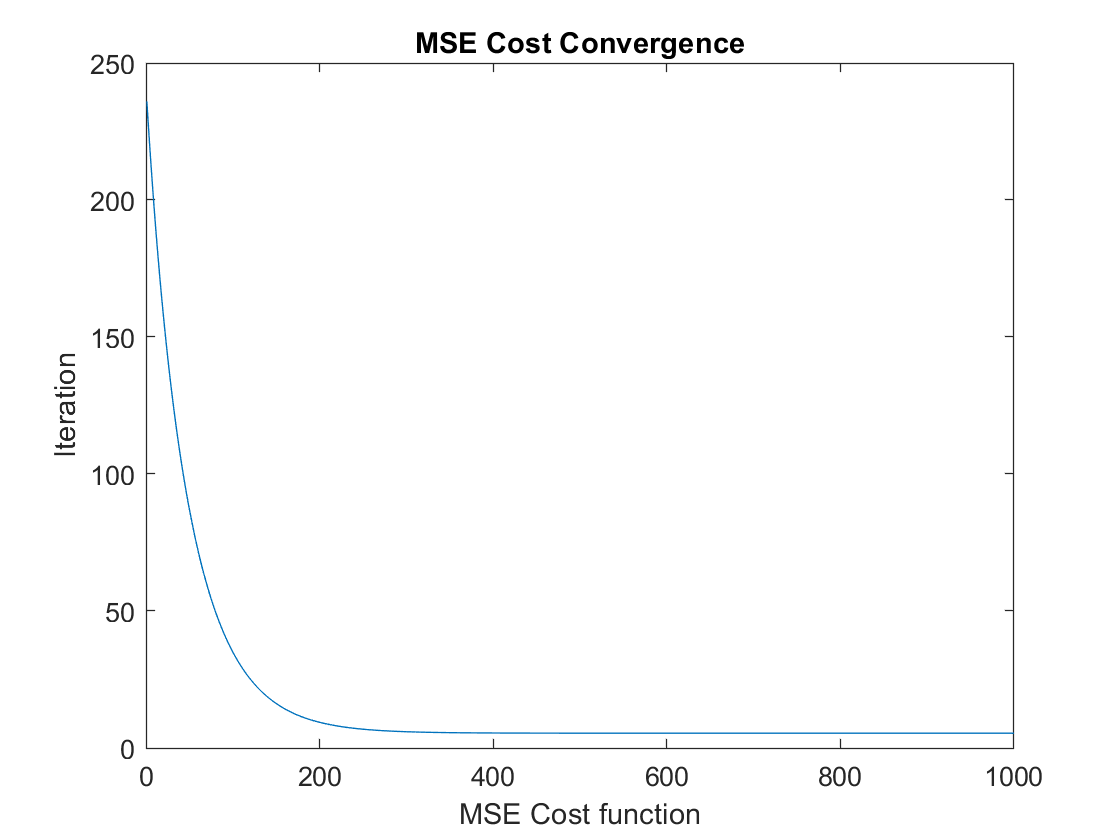

figure(2);

%% Add code:
% %add the lines of code to plot the MSE cost convergence

plot(Cost_J);xlabel('MSE Cost function'); ylabel('Iteration');
title('MSE Cost Convergence');

**Part2-8 : Test the prediction model with a new dataset**

%%% Add Code:
% file the lines of code for data loading and extracting input and output


% Load the testing data "car_mpg_testingData.csv"
testData = load('car_mpg_testingData.csv');


%extract horse power as input which is in column 4
testCylinders = testData(:,2);
testDisplacement = testData(:,3);
testHorsePower = testData(:,4);


%extract mpg as target output
targetOutput = testData(:,1);

%Data normalization using the same mean and the same standard deviation calcualted with the training data
normalizedTestCylinders = (testCylinders - meanCylinders) ./ sigmaCylinders;
normalizedTestDisplacement = (testDisplacement - meanDisplacement) ./ sigmaDisplacement;
normalizedTestHorsePower = (testHorsePower - meanHorsePower) ./ sigmaHorsePower;

%add the bais term 
normalizedTestX = [normalizedTestCylinders, normalizedTestDisplacement, normalizedTestHorsePower];
[mt, kt] = size(normalizedTestX);
BiasTest = ones(mt, 1);
TestX = [BiasTest, normalizedTestX];

%make a prediction for the test data
H = TestX * W;

%calculate the error
errorTest = H - targetOutput;

%calculate the MSE error for the testing data

MSE = (1 / (2*mt) ) * sum(errorTest.^2);
fprintf("The mean square error is %0.5g",MSE);

The mean square error is 12.121